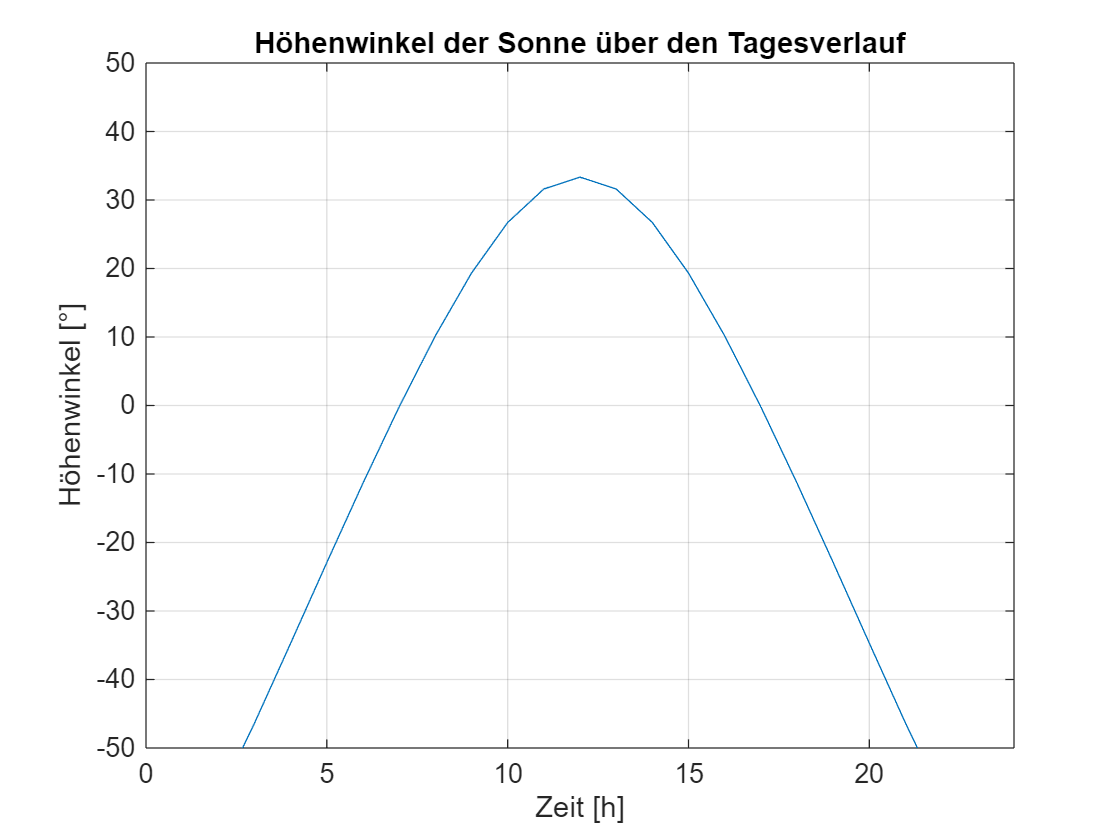

phi=38.1167; % geografische Breite von Palermo
t=0:1:24; % Tageszeiten
delta=Deklination(datetime('2025-01-28')); % Tag der Auswertung
H=Stundenwinkel(t);
a=Hoehenwinkel(phi,delta,t);
figure
plot(t,a)
xlabel("Zeit [h]");
ylabel("Höhenwinkel [°]");
title("Höhenwinkel der Sonne über den Tagesverlauf");
grid on;
ylim([-50 50]);
xlim([0 24]);

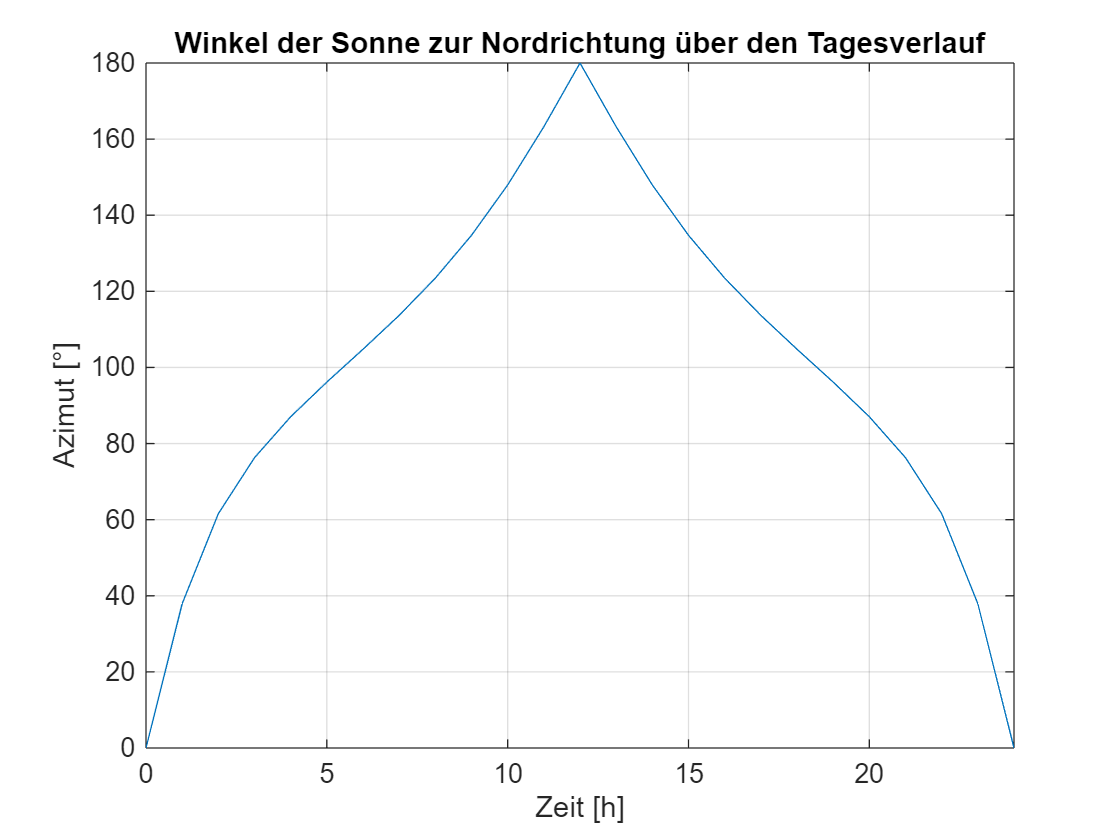


az=Azimut(delta,a,phi,t);
figure
plot(t,az)
xlabel("Zeit [h]");
ylabel("Azimut [°]");
title("Winkel der Sonne zur Nordrichtung über den Tagesverlauf");
grid on;
xlim([0 24]);

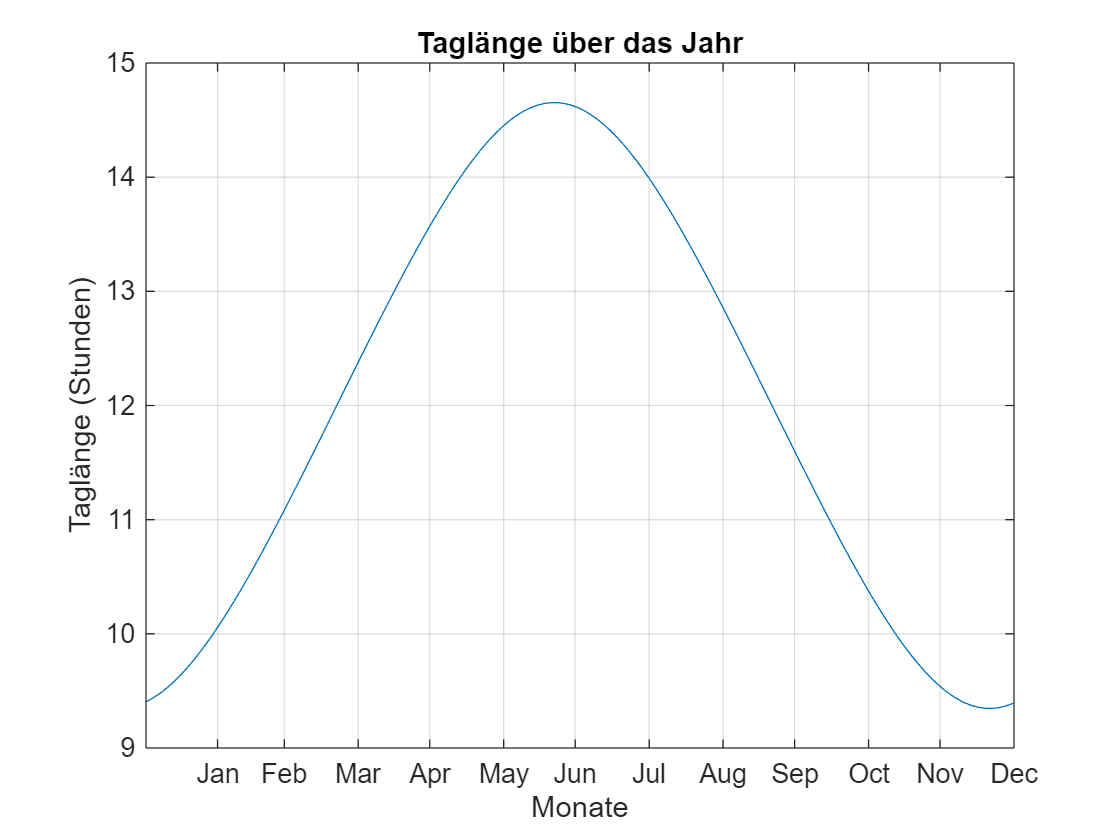


daylen=Taglaenge(phi);
figure
plot(1:365,daylen)
xlim([1,365]);
tage_pro_monat = [31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31];
tage_am_monat_ende = cumsum(tage_pro_monat);
xticks(tage_am_monat_ende);
months = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
xticklabels(months);
xlabel('Monate');
ylabel('Taglänge (Stunden)');
title('Taglänge über das Jahr');
grid on;

VnSa = Vertikal_nach_Sueden_ausgerichtet(phi)

Energie pro Tag an den jeweiligen Tagen (März, Juni, September, Dezember):
   1.0e+03 *

    1.1856    1.7587    1.1904    0.5796

Gesamte umgewandelte Energie innerhalb eines Jahres: 4714.30 kWh


VnSa = 4.7143e+03